%350
figure(1)

str_cnt = 'A1A2A3A4A5A6A7A8A9A10A11A12A13A14B1B2B3B4B5B6B7'

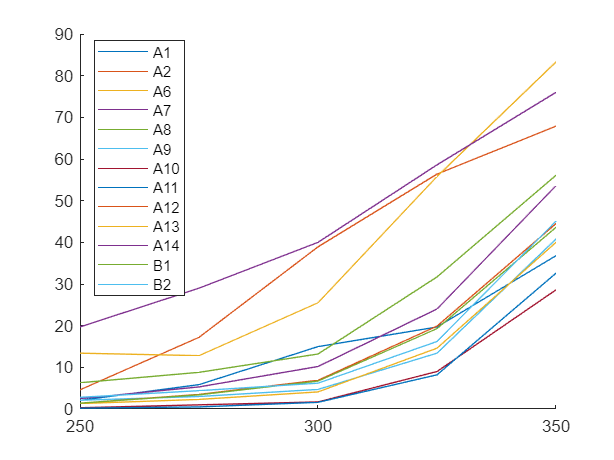

hold on
for i=1:21
    if sum(alcho(i,:)~=0)==5
        plot(temperatue(1,1:5),alcho(i,1:5));
    end
end
% legend(str_cnt(1,2,6,7,8,9,10,11,12,13,14,15,16))
legend('A1','A2', 'A6', 'A7', 'A8', 'A9', 'A10', 'A11', 'A12', 'A13', 'A14', 'B1', 'B2','Location','best')
hold off

C4=choose_C4

函数或变量 'C4choose' 无法识别。

C4(C4==0)=nan
plot(temperatue,C4,'LineWidth',1.5)
legend('A1','A2','A3', 'A4', 'A5', 'A6', 'A7', 'A8', 'A9', 'A10', 'A11', 'A12', 'A13', 'A14', 'B1', 'B2', 'B3', 'B4', 'B5', 'B6', 'B7')


xx=250:25:400;
temperatue_1=[250 275 300 325 350];
temperatue_2=[250 275 300 350 400];
temperatue_3=[250 275 300 325 350 400];
%5个数据点
P=zeros(7,21);
for i=[1,2]
    A_cnt=spline(temperatue_1,alchohol(1:5,i)',xx);
    i
    P(:,i)=A_cnt';
end

错误使用 vertcat
要串联的数组的维度不一致。

for i=[6,7,8,9,10,11,12,13,14,15,16]
    A_cnt=spline(temperatue_2,alchohol(1:5,i)',xx);
    P(:,i)=A_cnt';
end
for i=[3,4,5,17,18,19,20,21]
    A_cnt=spline(temperatue_3,alchohol(1:6,i)',xx);
    P(:,i)=A_cnt';
end
P
plot(xx,P)
grid on
colororder

clf;
tt=[250 275 300 325 350 400 450]

tt =    250   275   300   325   350   400   450


xx_t=250:25:450

xx_t =    250   275   300   325   350   375   400   425   450


s=spline(tt,alchohol(1:7,3)',xx_t)

s =     9.7000   19.2000   29.3000   37.6000   48.9000   66.2529   83.7000   93.1221   86.4000


fittype_1 = fittype('1./(a*exp(-k*(x-250))+b)','dependent',{'y'},'independent',{'x'},'coefficients',{'a','b','k'})

fittype_1 =      General model:
     fittype_1(a,b,k,x) = 1./(a*exp(-k*(x-250))+b)

[x,fobj]=fit(xx_t',s',fittype_1)

x =      General model:
     x(x) = 1./(a*exp(-k*(x-250))+b)
     Coefficients (with 95% confidence bounds):
       a =     0.08822  (0.03193, 0.1445)
       b =    0.009913  (0.007995, 0.01183)
       k =     0.02312  (0.01427, 0.03197)

fobj = 包含以下字段的 struct :
           sse: 136.9437
       rsquare: 0.9822
           dfe: 6
    adjrsquare: 0.9762
          rmse: 4.7774


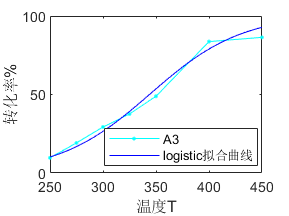

plot(tt,alchohol(1:7,3)','.-c')
hold on
plot(x,'b')
xlabel('温度T')
ylabel('转化率%')
legend('A3','logistic拟合曲线','Location','best')
hold off

tt=250:25:400

tt =    250   275   300   325   350   375   400


s=P_1(1:7,12)

s =     6.1700
    8.1100
   11.2200
   16.0613
   22.2600
   29.2088
   36.3000


fittype_1 = fittype('poly2')

fittype_1 =      Linear model Poly2:
     fittype_1(p1,p2,p3,x) = p1*x^2 + p2*x + p3

[x,fobj]=fit(xx',s,fittype_1)

x =      Linear model Poly2:
     x(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =   0.0009079  (0.0006931, 0.001123)
       p2 =      -0.385  (-0.5249, -0.245)
       p3 =       45.42  (23.06, 67.78)

fobj = 包含以下字段的 struct :
           sse: 0.7857
       rsquare: 0.9990
           dfe: 4
    adjrsquare: 0.9985
          rmse: 0.4432


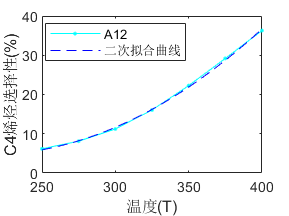

plot(tt,s','.-c')
hold on
plot(x,'b--')
xlabel('温度(T)')
ylabel('C4烯烃选择性(%)')
legend('A12','二次拟合曲线','Location','best')
hold off

A2=P(:,2)

函数或变量 'P' 无法识别。

tmp=xx
A1=P(1:5,1)
tmp5=tmp(1:5)
A3=P(:,3)
A4=P(:,4)
a5=P(:,5)
a6=P(:,6)
a7=P(:,7)
a8=P(:,8)
a9=P(:,9)
a10=P(:,10)
a11=P(:,11)
a12=P(:,12)
a13=P(:,13)
a14=P(:,14)
b1=P(:,15)
b2=P(:,16)
b3=P(:,17)
b4=P(:,18)
b5=P(:,19)
b6=P(:,20)
b7=P(:,21)

save choose_c4.mat choose_C4

xx=250:25:400;
temperatue_1=[250 275 300 325 350];
temperatue_2=[250 275 300 350 400];
temperatue_3=[250 275 300 325 350 400];
%5个数据点
P_1=zeros(7,21);
for i=[1,2]
    A_cnt=[choose_C4(1:5,i);0;0]
    P_1(:,i)=A_cnt;
end

A_cnt =    34.0500
   37.4300
   46.9400
   49.7000
   47.2100
         0
         0


A_cnt =    18.0700
   17.2800
   19.6000
   30.6200
   39.1000
         0
         0


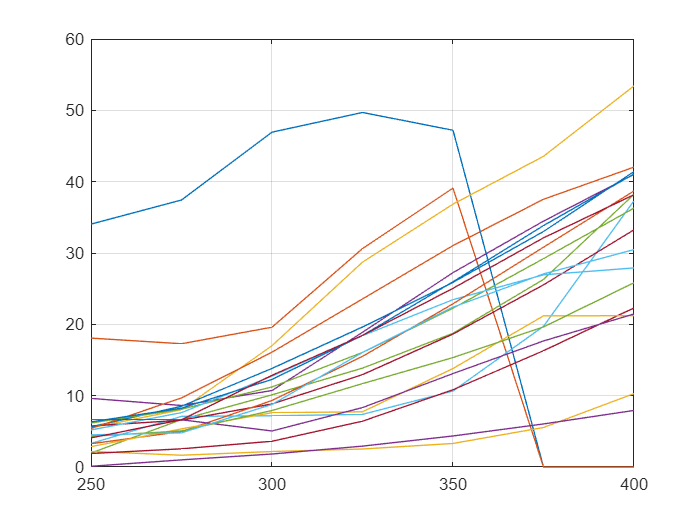

for i=[6,7,8,9,10,11,12,13,14,15,16]
    A_cnt=spline(temperatue_2,choose_C4(1:5,i)',xx);
    P_1(:,i)=A_cnt';
end
for i=[3,4,5,17,18,19,20,21]
    A_cnt=spline(temperatue_3,choose_C4(1:6,i)',xx);
    P_1(:,i)=A_cnt';
end
plot(xx,P_1)
grid on

xx=250:25:450;
temperatue_1=[250 275 300 325 350];
temperatue_2=[250 275 300 350 400];
temperatue_3=[250 275 300 325 350 400 ];
P2=zeros(7,21);
a=[1,2]

a =      1     2


b=[6,7,8,9,10,11,12,13,14,15,16]%5

b =      6     7     8     9    10    11    12    13    14    15    16


c=[4,5,17,18,19,20,21]%6

c =      4     5    17    18    19    20    21


tmp=1

tmp = 1

for i=1:21
    if ismember(i,a)
        A_cnt=PS(tmp:tmp+5-1);
        P2(:,i)=[A_cnt;0;0];
        tmp=tmp+5;
    elseif ismember(i,b)
        A_cnt=PS(tmp:tmp+5-1);
        P2(:,i)=[A_cnt(1:3);0;A_cnt(4:5);0];
        tmp=tmp+5;
    elseif ismember(i,c)
        A_cnt=PS(tmp:tmp+6-1);
        P2(:,i)=[A_cnt;0];
        tmp=tmp+6
    elseif i==3
        A_cnt=PS(tmp:tmp+7-1);
        P2(:,i)=A_cnt;
        tmp=tmp+7
    end
end

tmp = 18

tmp = 24

tmp = 30

tmp = 91

tmp = 97

tmp = 103

tmp = 109

tmp = 115

P2(P2==0)=nan

P2 =     0.7040    0.8320    0.5320    0.3870    0.2900    0.4420    1.1300    0.3530    0.1110    0.0070       NaN    0.0890    0.0700    0.0470    0.0890    0.0900    0.0110    0.0360    0.0910    0.1250    0.1800
    2.1900    2.9710    1.5470    1.0430    0.8260    0.9070    1.9050    0.7460    0.2910    0.0170    0.0050    0.2820    0.1760    0.1360    0.2820    0.2190    0.0330    0.0740    0.1940    0.3600    0.5230
    7.0260    7.6290    4.9750    3.1600    2.1060    1.8290    3.5350    1.8210    0.7610    0.0370    0.0290    0.7760    0.5180    0.3660    0.8260    0.5800    0.0870    0.1520    0.4600    1.1070    1.5050
    9.7820   17.2640   10.7930    8.1840    3.9290       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.2540    0.5040    1.1440    2.5470    3.2840
   17.3740   26.5410   18.0330   16.4780    6.9020    5.9380   10.9240    8.2120    4.1570    0.2980    0.3570    4.4320    3.4340    2.6030    5.0150 

P3=zeros(7,21);
a=[1,2]

a =      1     2


b=[6,7,8,9,10,11,12,13,14,15,16]%5

b =      6     7     8     9    10    11    12    13    14    15    16


c=[4,5,17,18,19,20,21]%6

c =      4     5    17    18    19    20    21


tmp=1

tmp = 1

for i=1:21
    if ismember(i,a)
        A_cnt=P_alc(tmp:tmp+5-1);
        P3(:,i)=[A_cnt;0;0];
        tmp=tmp+5;
    elseif ismember(i,b)
        A_cnt=P_alc(tmp:tmp+5-1);
        P3(:,i)=[A_cnt;0;0];
        tmp=tmp+5;
    elseif ismember(i,c)
        A_cnt=P_alc(tmp:tmp+6-1);
        P3(:,i)=[A_cnt;0];
        tmp=tmp+6
    elseif i==3
        A_cnt=P_alc(tmp:tmp+7-1);
        P3(:,i)=A_cnt;
        tmp=tmp+7
    end
end

tmp = 18

tmp = 24

tmp = 30

tmp = 91

tmp = 97

tmp = 103

tmp = 109

tmp = 115

alchohol=P3

alchohol =     2.0700    4.6000    9.7000    4.0000   14.8000   13.4000   19.7000    6.3000    2.1000    0.3000    0.2000    1.4000    1.3000    2.5000    1.4000    2.8000    0.4000    0.5000    2.1000    2.8000    4.4000
    5.8500   17.2000   19.2000   12.1000   12.4000   12.8000   29.0000    8.8000    3.0000    1.0000    0.5000    3.5000    2.3000    5.3000    3.4000    4.4000    0.6000    1.1000    3.8000    7.5000    7.9000
   14.9700   38.9200   29.3000   29.5000   20.8000   25.5000   40.0000   13.2000    4.7000    1.7000    1.6000    6.9000    4.1000   10.2000    6.7000    6.2000    1.1000    3.0000    5.8000   12.6000   11.7000
   19.6800   56.3800   37.6000   43.3000   28.3000   55.8000   58.6000   31.7000   13.4000    9.0000    8.2000   19.9000   14.6000   24.0000   19.3000   16.2000    3.3000    6.1000    9.8000   15.9000   17.8000
   36.8000   67.8800   48.9000   60.5000   36.8000   83.3000   76.0000   56.1000   40.8000   28.6000   32.6000   44.5000   40.0000   53.6000   43

xx=250:25:400;
temperatue_1=[250 275 300 325 350];
temperatue_2=[250 275 300 350 400];
temperatue_3=[250 275 300 325 350 400];
%5个数据点
P=zeros(7,21);
for i=[1,2]
    A_cnt=alchohol(1:5,i)
    P(:,i)=[A_cnt;nan;nan];
end

A_cnt =     2.0700
    5.8500
   14.9700
   19.6800
   36.8000


A_cnt =     4.6000
   17.2000
   38.9200
   56.3800
   67.8800


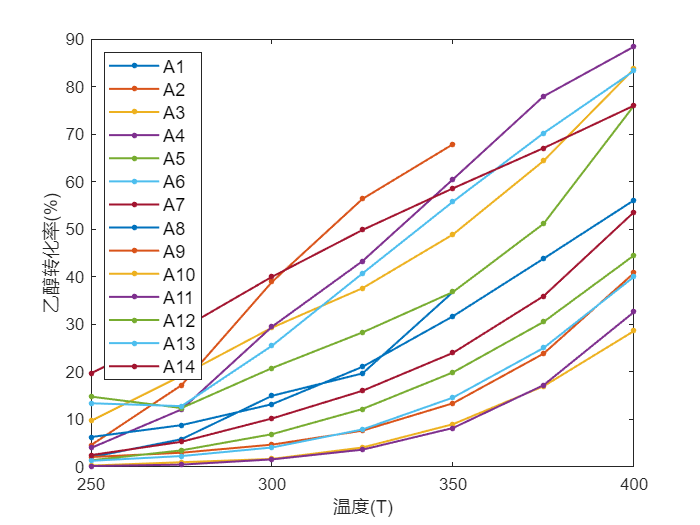

for i=[6,7,8,9,10,11,12,13,14,15,16]
    A_cnt=spline(temperatue_2,alchohol(1:5,i)',xx);
    P(:,i)=A_cnt';
end
for i=[3,4,5,17,18,19,20,21]
    A_cnt=spline(temperatue_3,alchohol(1:6,i)',xx);
    P(:,i)=A_cnt';
end
plot(xx,P(:,1:14),'.-','LineWidth',1.2,'MarkerSize',10)
ylabel("乙醇转化率(%)")
xlabel("温度(T)")
legend('A1','A2','A3', 'A4', 'A5', 'A6', 'A7', 'A8', 'A9', 'A10', 'A11', 'A12', 'A13', 'A14','Fontsize',11,'Location','northwest')

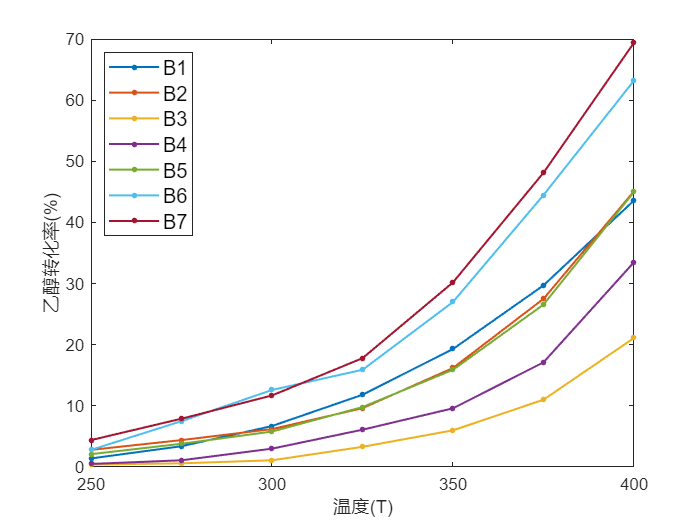

plot(xx,P(:,15:21),'.-','LineWidth',1.2,'MarkerSize',10)
ylabel("乙醇转化率(%)")
xlabel("温度(T)")
legend('B1', 'B2', 'B3', 'B4', 'B5', 'B6', 'B7','Fontsize',12,'Location','northwest')

x=[250,275,300,325,350,400,450]

x =    250   275   300   325   350   400   450


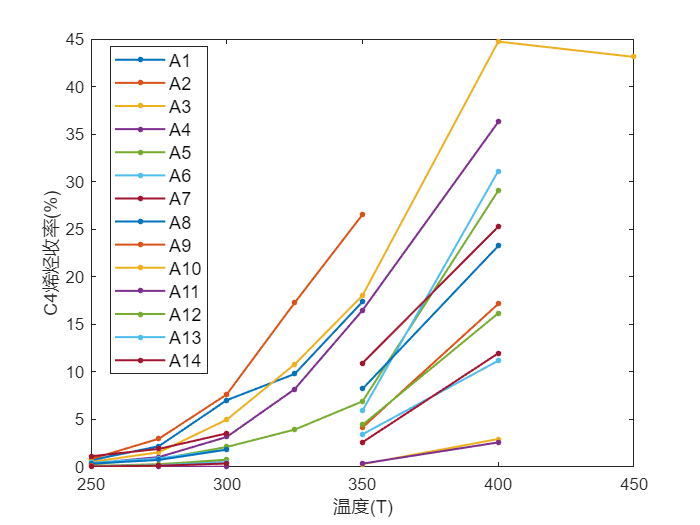

plot(x,P2(:,1:14),'.-','LineWidth',1.2,'MarkerSize',10)
ylabel("C4烯烃收率(%)")
xlabel("温度(T)")
legend('A1','A2','A3', 'A4', 'A5', 'A6', 'A7', 'A8', 'A9', 'A10', 'A11', 'A12', 'A13', 'A14','Fontsize',11,'Location','best')

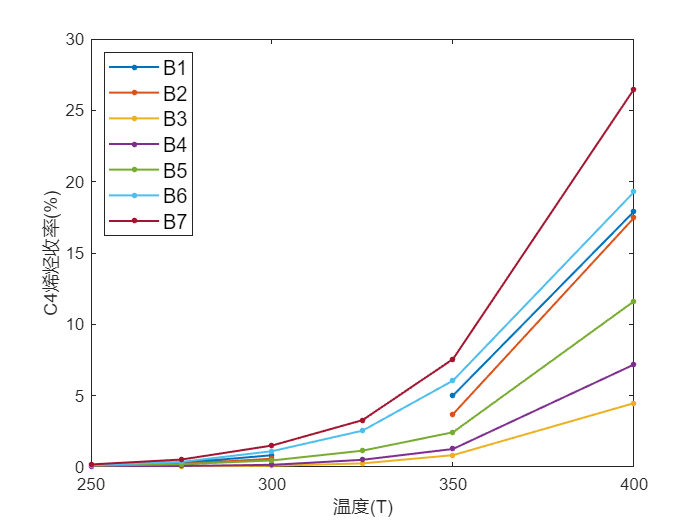

plot(x,P2(:,15:21),'.-','LineWidth',1.2,'MarkerSize',10)
ylabel("C4烯烃收率(%)")
xlabel("温度(T)")
legend('B1', 'B2', 'B3', 'B4', 'B5', 'B6', 'B7','Fontsize',12,'Location','northwest')

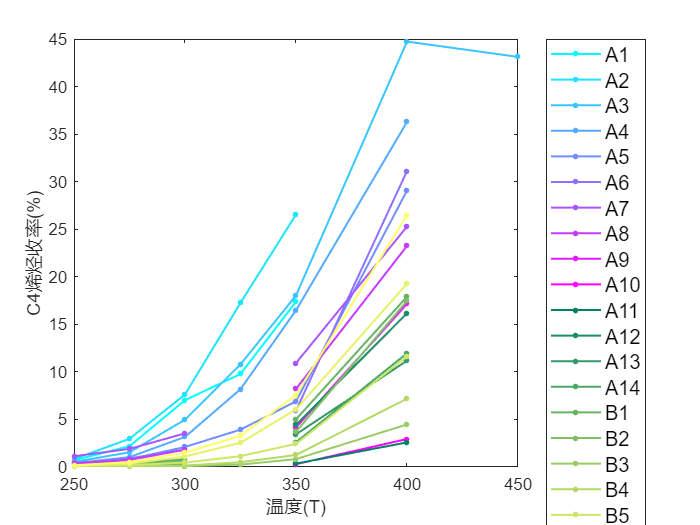

b =          0    0.5000    0.4000
    0.1000    0.5500    0.4000
    0.2000    0.6000    0.4000
    0.3000    0.6500    0.4000
    0.4000    0.7000    0.4000
    0.5000    0.7500    0.4000
    0.6000    0.8000    0.4000
    0.7000    0.8500    0.4000
    0.8000    0.9000    0.4000
    0.9000    0.9500    0.4000


c=colormap(cool(10));
b=colormap(summer(11))

c=[c;b]

c =          0    1.0000    1.0000
    0.1111    0.8889    1.0000
    0.2222    0.7778    1.0000
    0.3333    0.6667    1.0000
    0.4444    0.5556    1.0000
    0.5556    0.4444    1.0000
    0.6667    0.3333    1.0000
    0.7778    0.2222    1.0000
    0.8889    0.1111    1.0000
    1.0000         0    1.0000


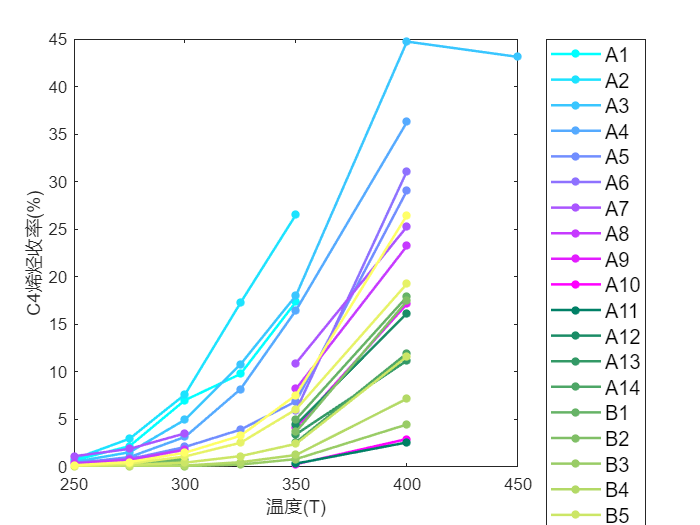

clf
for i=1:21 
    plot(x,P2(:,i),'.-','color',c(i,:),'LineWidth',1.5,'MarkerSize',15);hold on %化曲线，每次循环根换数据和颜色
end
hold off
ylabel("C4烯烃收率(%)")
xlabel("温度(T)")
legend('A1','A2','A3', 'A4', 'A5', 'A6', 'A7', 'A8', 'A9', 'A10', 'A11', 'A12', 'A13', 'A14','B1', 'B2', 'B3', 'B4', 'B5', 'B6', 'B7','Fontsize',12,'Location','bestoutside')

P2T=P2'

P2T =     0.7040    2.1900    7.0260    9.7820   17.3740       NaN       NaN
    0.8320    2.9710    7.6290   17.2640   26.5410       NaN       NaN
    0.5320    1.5470    4.9750   10.7930   18.0330   44.7280   43.1180
    0.3870    1.0430    3.1600    8.1840   16.4780   36.2780       NaN
    0.2900    0.8260    2.1060    3.9290    6.9020   29.0620       NaN
    0.4420    0.9070    1.8290       NaN    5.9380   31.1140       NaN
    1.1300    1.9050    3.5350       NaN   10.9240   25.2790       NaN
    0.3530    0.7460    1.8210       NaN    8.2120   23.2430       NaN
    0.1110    0.2910    0.7610       NaN    4.1570   17.1510       NaN
    0.0070    0.0170    0.0370       NaN    0.2980    2.9420       NaN


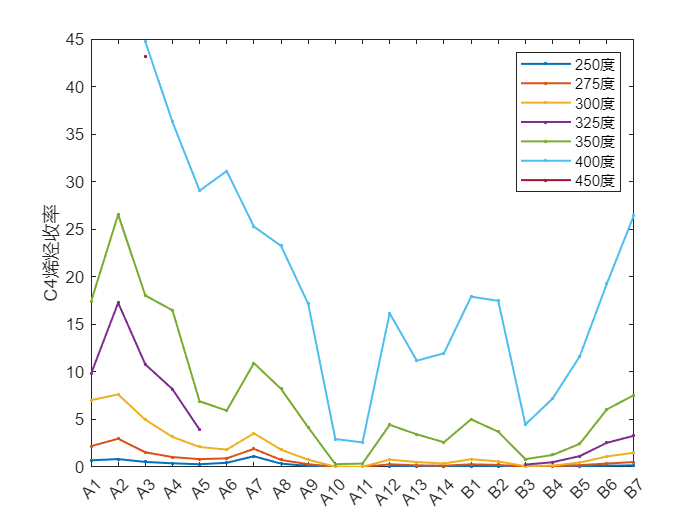

clf;
plot(P2T,'.-','LineWidth',1.2)
legend('250度','275度', '300度', '325度', '350度', '400度', '450度')
ylabel("C4烯烃收率")

% xlabel("催化剂组合")
xticks(1:21)
xticklabels({'A1' ,'A2' ,'A3', 'A4' ,'A5' ,'A6' ,'A7' ,'A8', 'A9' ,'A10' ,'A11' ,'A12' ,'A13' ,'A14' ,'B1' ,'B2' ,'B3' ,'B4' ,'B5' ,'B6' ,'B7'})
xlim([1 21])

% [A1 A2 A3 A4 A5 A6 A7 A8 A9 A10 A11 A12 A13 A14 B1 B2 B3 B4 B5 B6 B7]

choose_C4(1:5,2)

ans =    18.0700
   17.2800
   19.6000
   30.6200
   39.1000


spline(temperatue_1,choose_C4(1:5,2),xx)

ans =    18.0700   17.2800   19.6000   30.6200   39.1000   29.5925  -13.3500



fit_2=fittype('poly2')

fit_2 =      Linear model Poly2:
     fit_2(p1,p2,p3,x) = p1*x^2 + p2*x + p3

fit_1=fittype('poly1')

fit_1 =      Linear model Poly1:
     fit_1(p1,p2,x) = p1*x + p2

%A1
[x,fobj_0]=fit(temperatue_1',choose_C4(1:5,1),fit_2)

x =      Linear model Poly2:
     x(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =   -0.002113  (-0.007302, 0.003075)
       p2 =       1.422  (-1.695, 4.539)
       p3 =      -190.8  (-653.6, 272)

fobj_0 = 包含以下字段的 struct :
           sse: 15.9045
       rsquare: 0.9160
           dfe: 2
    adjrsquare: 0.8319
          rmse: 2.8200


[x_1,fobj_1]=fit(temperatue_1',choose_C4(1:5,1),fit_1)

x_1 =      Linear model Poly1:
     x_1(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.1544  (0.006774, 0.3019)
       p2 =      -3.242  (-47.82, 41.34)

fobj_1 = 包含以下字段的 struct :
           sse: 40.3245
       rsquare: 0.7869
           dfe: 3
    adjrsquare: 0.7159
          rmse: 3.6663


L=zeros(7,21)

L =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


%
%A1-2
clf;
hold on
for i=[1,2]
    [x_2,fobj_2]=fit(temperatue_1',P_1(1:5,i),fit_2);
    [x_1,fobj_1]=fit(temperatue_1',P_1(1:5,i),fit_1);
    subplot(7,3,i)
    plot(x_2,'m',temperatue_1,P_1(1:5,i)')
    if fobj_1.rsquare>fobj_2.rsquare
        L(1,i)=fobj_1.sse;
        L(2,i)=fobj_1.rsquare;
        L(3,i)=fobj_1.adjrsquare;
        L(4,i)=fobj_1.rmse;
        L(6,i)=x_1.p1;
        L(7,i)=x_1.p2;
    else
        L(1,i)=fobj_2.sse;
        L(2,i)=fobj_2.rsquare;
        L(3,i)=fobj_2.adjrsquare;
        L(4,i)=fobj_2.rmse;
        L(5,i)=x_2.p1;
        L(6,i)=x_2.p2;
        L(7,i)=x_2.p3;
    end
end
for i=[6,7,8,9,10,11,12,13,14,15,16,3,4,5,17,18,19,20,21]
    [x_2,fobj_2]=fit(xx',P_1(1:7,i),fit_2);
    [x_1,fobj_1]=fit(xx',P_1(1:7,i),fit_1);
    subplot(7,3,i)
    plot(x_2,'m',xx,P_1(1:7,i)')
    if fobj_1.rsquare>fobj_2.rsquare
        L(1,i)=fobj_1.sse;
        L(2,i)=fobj_1.rsquare;
        L(3,i)=fobj_1.adjrsquare;
        L(4,i)=fobj_1.rmse;
        L(6,i)=x_1.p1;
        L(7,i)=x_1.p2;
    else
        L(1,i)=fobj_2.sse;
        L(2,i)=fobj_2.rsquare;
        L(3,i)=fobj_2.adjrsquare;
        L(4,i)=fobj_2.rmse;
        L(5,i)=x_2.p1;
        L(6,i)=x_2.p2;
        L(7,i)=x_2.p3;
    end
    disp("--")
end

--
--
--
--
--
--
--
--
--
--
--
--
--
--
--
--
--
--
--


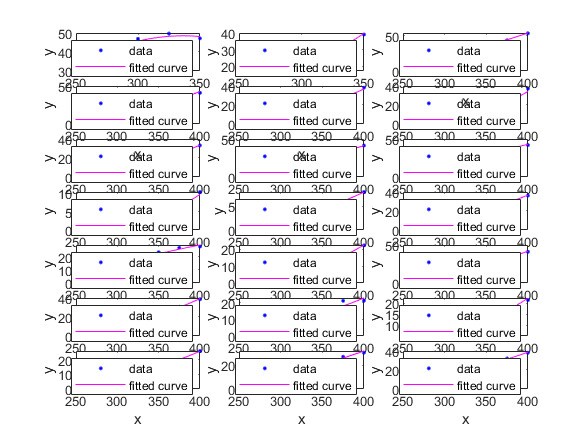

hold off

%%A，B组C4选择
h=plot(xx,P_1(:,1:14),'.-','LineWidth',1.2,'MarkerSize',10)

h =   14×1 Line 数组:

  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line


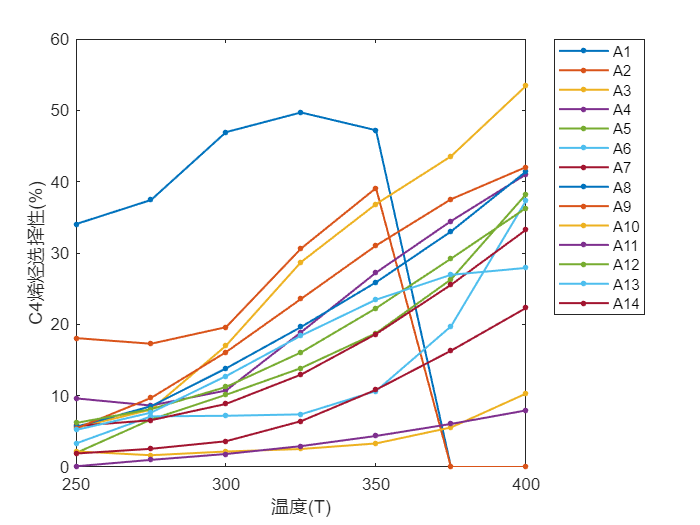

ylabel("C4烯烃选择性(%)")
xlabel("温度(T)")
legend('A1','A2','A3', 'A4', 'A5', 'A6', 'A7', 'A8', 'A9', 'A10', 'A11', 'A12', 'A13', 'A14','Location','bestoutside')

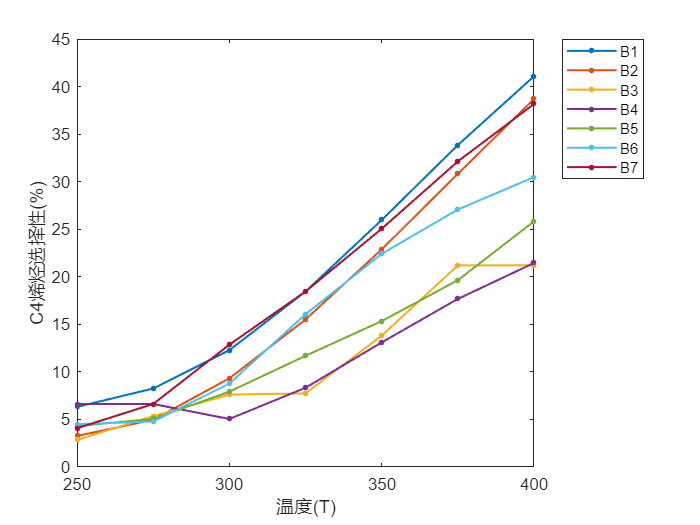

P_2 =    34.0500   37.4300   46.9400   49.7000   47.2100         0         0
   18.0700   17.2800   19.6000   30.6200   39.1000         0         0
    5.5000    8.0400   17.0100   28.7200   36.8500   43.5561   53.4300
    9.6200    8.6200   10.7200   18.8900   27.2500   34.4692   41.0200
    1.9600    6.6500   10.1200   13.8600   18.7500   26.3003   38.2300
    3.3000    7.1000    7.1800    7.3792   10.6500   19.7233   37.3300
    5.7500    6.5600    8.8400   12.9458   18.6400   25.5367   33.2500
    5.6300    8.5200   13.8200   19.6275   25.8900   33.0175   41.4200
    5.4000    9.6800   16.1000   23.5608   31.0400   37.5342   42.0400
    2.1900    1.6500    2.1700    2.5237    3.3000    5.5412   10.2900


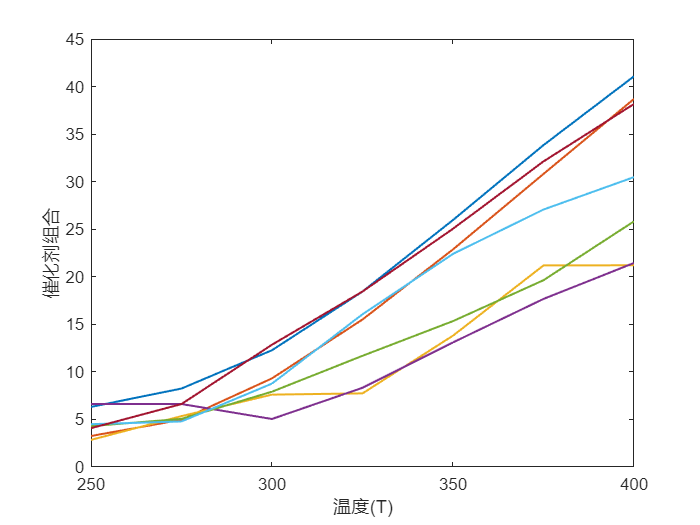

plot(xx,P_1(:,15:21),'.-','LineWidth',1.2,'MarkerSize',10)
ylabel("C4烯烃选择性(%)")
xlabel("温度(T)")
legend('B1', 'B2', 'B3', 'B4', 'B5', 'B6', 'B7','Location','bestoutside')